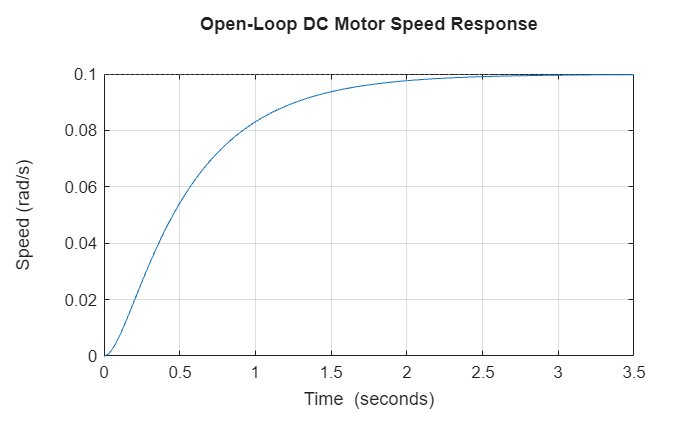

J = 0.01;     % Rotor inertia (kg*m^2)
b = 0.1;      % Friction coefficient (N*m*s)
K = 0.01;     % Motor constant
R = 1;        % Armature resistance (Ohm)
L = 0.5;      % Armature inductance (H)

s = tf('s');

% DC motor transfer function (angular speed / voltage)
P_motor = K / ((J*s + b)*(L*s + R) + K^2);

% Open-loop step response
step(P_motor)
grid on
title('Open-Loop DC Motor Speed Response')
xlabel('Time')
ylabel('Speed (rad/s)')